# let's look at some convoluted graphics functions

## Preprocessing

Set save path and make up some data. Fetch graphics scrut from setup_graphics().


path_save = 'C:\Users\everett\Pictures';

n = 100;
x = linspace(0,6*pi,n)';

fn1 = @(x) sin(x);
fn2 = @(x) cos(x)+rand;

f = setup_graphics('ppt','lassonde')

f = struct with fields:
    dest: 'ppt'
       W: 29.2100
       H: 12.0900
      Th: 18
      Tb: 12
       F: 'Arial'
     lw1: 2
     lw2: 3
      ms: 2
     Col: {6×1 cell}
    ColG: [39×3 double]


## Plot first

Plot the stuff you want. Always name figures. Limits and labelling can be set here as well, but most graphical parameters can be defined in a fucntional manner.

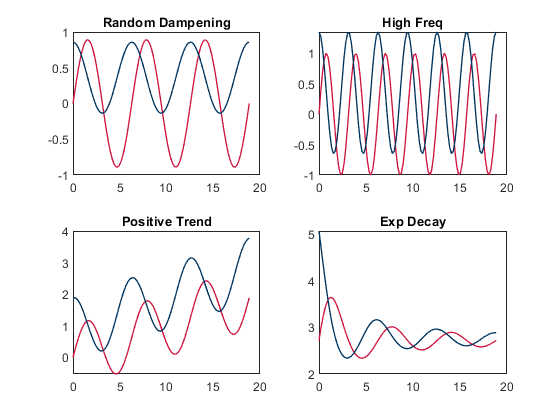

kill %close all figures, not my script - super useful

fh = figure;
fh.Name = 'sin wave transofmrations';

for ii = 1:4

    subplot(2,2,ii)
    for iii = 1:2
        y = nan(n,4);
        descriptions = {'Random Dampening','High Freq','Positive Trend','Exp Decay'};

        if iii == 1
            fn = fn1;
        elseif iii == 2
            fn = fn2;
        end
        
        y(:,1) = fn(x)*rand;
        y(:,2) = fn(x/0.5);
        y(:,3) = fn(x) + x/10;
        y(:,4) = exp(1+fn(x)./(x+2));
            
        plot(x(:,1),y(:,ii),'-','Color',f.Col{iii+2},'LineWidth',f.lw1/2)
        hold on
        
    end
    
    title(descriptions{ii})
end

wow it looks like garbage

## Make figure text lower case

Simple, makes everything lower case. This ensures consistensy, but could be annoying if you want upper-case accronyms. There might be some exceptions I haven't run into (e.g. character x-tick labels).

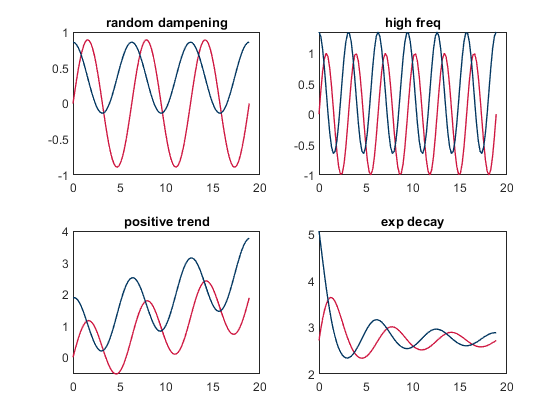

apply_lower(gcf);

## Resize to powerpoint dimensions

This script resizes according to width and height f.W and f.H, respectively. These dims are determined based on destimation (i.e. ppt, word, pub) input in the 'setup_graphics()' function. It also applies white background, font and font size, also based on destination.

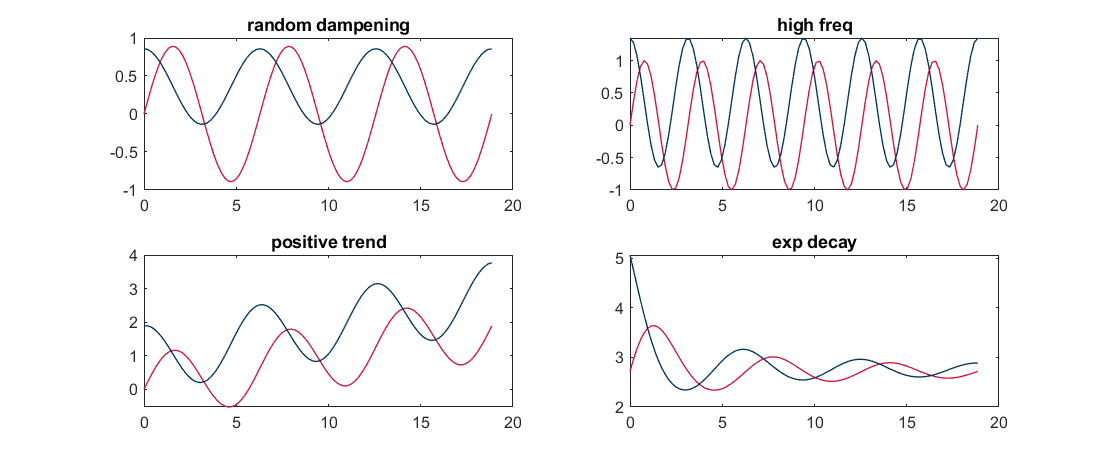

apply_graphics(f,gcf);

## Fix the margins between subplots

Accepts four arguments, margins and a buffer space for legend at the bottom. Could be easily adapted to have buffer space on the side.

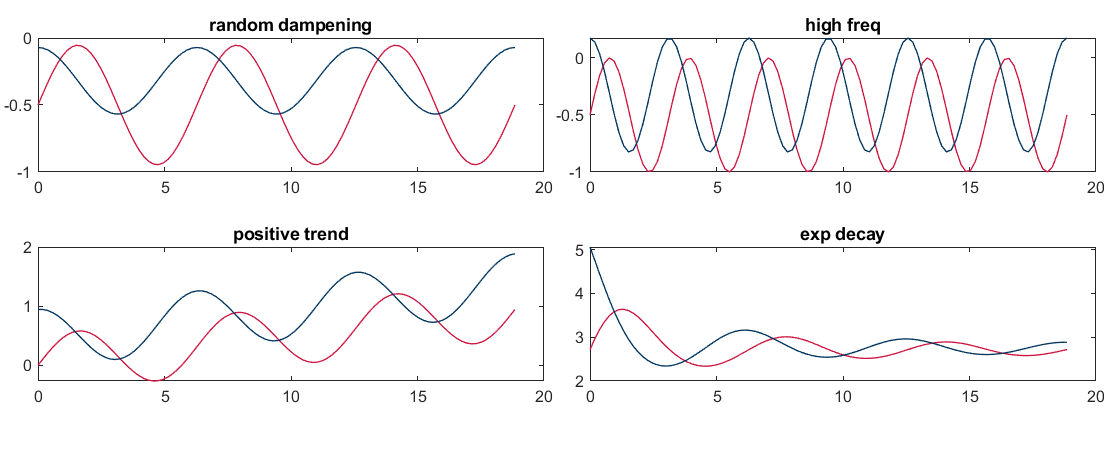

margin_right = 1;
margin_left = 0.2;
margin_bottom = 1;
margin_top = 1;
margin_legend = 1;

fix_margins(margin_right,margin_left,...
    margin_bottom,margin_top,...
    margin_legend)

## Add a legend, centered at the bottom of the plot

What it says, adds a legend at the bottom left, right, or center. Adds a border, but could be turned off. Should be done outside a subplot loop, as it only adds a legend to the most recent subplot.

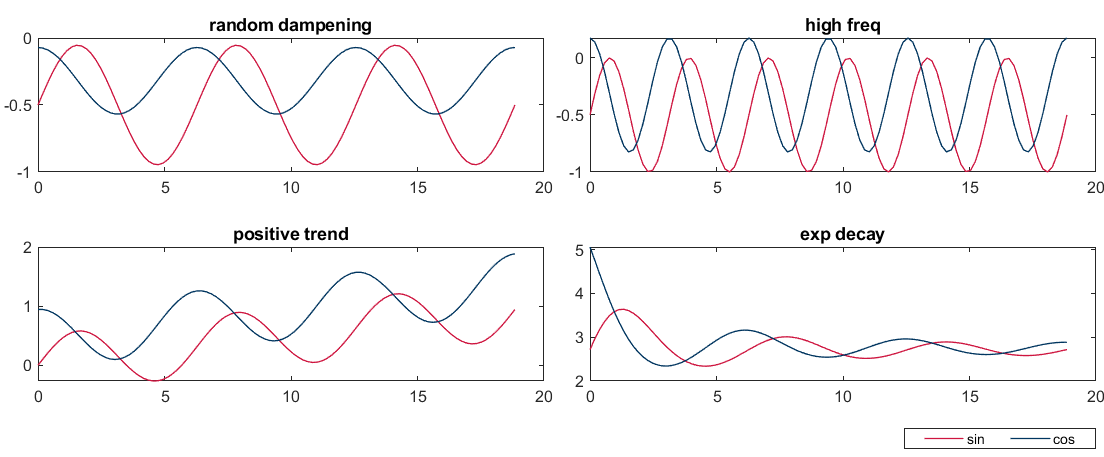

lh = legend({'sin','cos'});
fix_legend(lh,'right')

## Make uniform limits across subplots

Finds the largest limits across subplots and applies to all subplots. This is very nice for making comparisons between subplots. Option to have neg-limit = pos-limit, and add a buffer ratio so the data doesn't bottom out against the axis border.

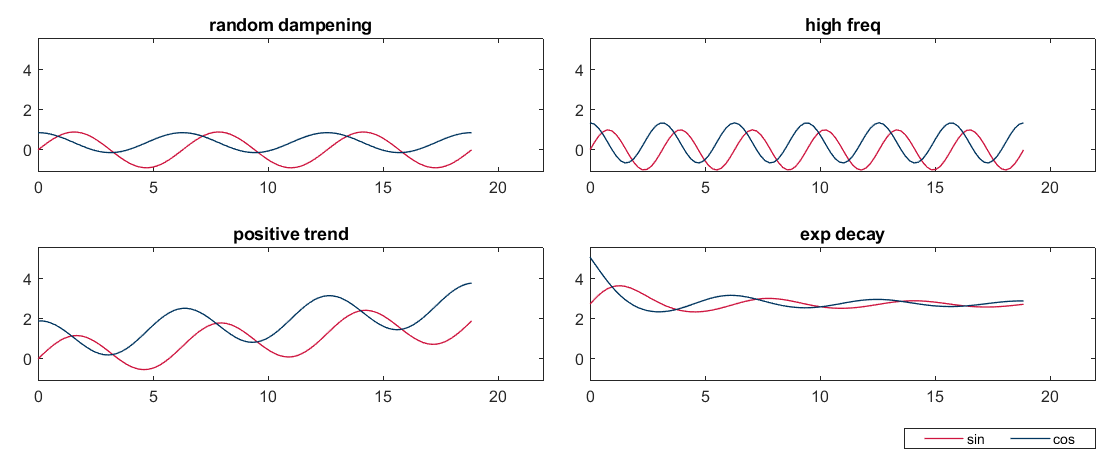

fh = apply_sqlims(gcf,'buff_ratio',1.1);

## Insert a zoom window

Adds a zoom window to subplots. This script is pretty sloppy, and could easily be improved, or adapted to have a non-uniform zoom window across subplots. For now it's good enough...

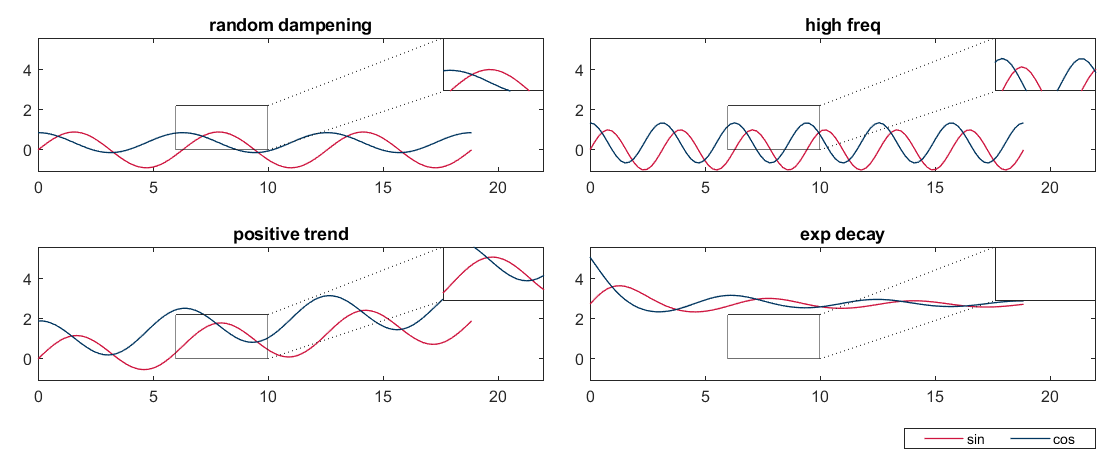

extent_horz = [6 10];
extent_vert = [0 2.2];
ratio = [0.2,0.4];
insert_zoombox(gcf,extent_horz,extent_vert,ratio)